format long
% Pergunta 2.1.1-----------------------------------------------
y0 = [50000,0,0,0,50000]; 

eps = 1e-4;
nmax = 100;

[x, normas, it] = NewtonMatriz(@Fx, @JF, y0, eps, nmax)

x = 1.0e+04 *

   0.333333333333334   0.333333333333333
                   0                   0
                   0                   0
                   0                   0
   9.666666666666666   9.666666666666666


normas = 1.0e+04 *

   6.599663291074443   0.000000000000001


it =      2



% Pergunta 2.1.2
y0 = [100000,1,100,1,100000]; 

eps = 1e-4;
nmax = 100;

[x, normas, it] = NewtonMatriz(@Fx2, @JF2, y0, eps, nmax)

x = 1.0e+05 *

  -0.002686334144285   0.007412389065167   0.010828330207262   0.011335145269526   0.011346815559762   0.011346821754269   0.011346821754271
   0.000021606757469   0.000015548937439   0.000013499851010   0.000013195832931   0.000013188832391   0.000013188828675   0.000013188828675
   0.001003099232562   0.000721863390850   0.000626734030196   0.000612619913226   0.000612294911359   0.000612294738850   0.000612294738850
   0.000013421902568   0.000009658845092   0.000008385973009   0.000008197120005   0.000008192771340   0.000008192769031   0.000008192769031
   1.001648206251686   0.991840539761452   0.988523049938523   0.988030841864312   0.988019507925149   0.988019501909175   0.988019501909173


normas = 1.0e+05 *

   1.002687688874050   0.014080258410314   0.004762714354832   0.000706632600469   0.000016271433412   0.000000008636761   0.000000000000002


it =      7


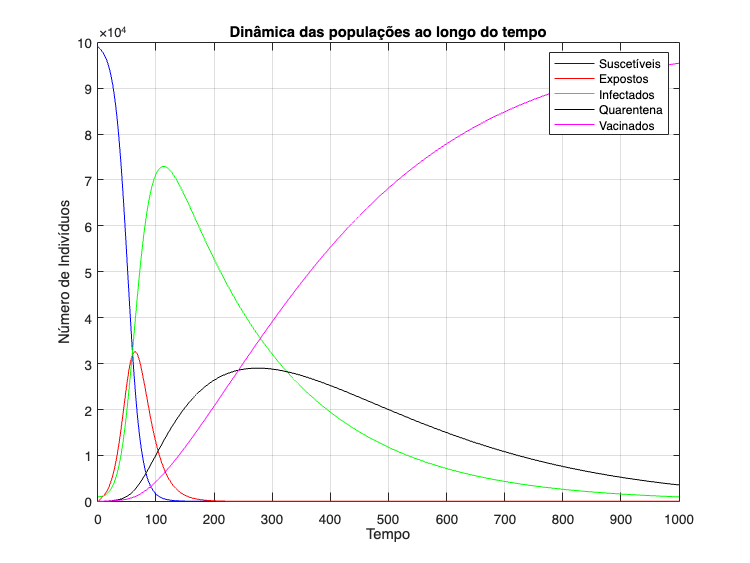


% Pergunta 2.3.1.a) ----------------------------------------------
k = 5;
a = 0; 
b = 1000; 
n = b*10; % número de passos no intervalo [0, 1000] com τ = 0.1
ya = [99000; 0; 1000; 0; 0];
[Y, M] = Heun(@Fx231, ya, a, b, n, k);

t = linspace(a, b, n+1);
figure;
plot(t, Y(1, :), 'b', 'DisplayName', 'Suscetíveis');
hold on;
plot(t, Y(2, :), 'r', 'DisplayName', 'Expostos');
plot(t, Y(3, :), 'g', 'DisplayName', 'Infectados');
plot(t, Y(4, :), 'k', 'DisplayName', 'Quarentena');
plot(t, Y(5, :), 'm', 'DisplayName', 'Vacinados');
title('Dinâmica das populações ao longo do tempo');
xlabel('Tempo');
ylabel('Número de Indivíduos');
legend show;
grid on;


% Pergunta 2.3.1.b) ----------------------------------------------
k = 5;
a = 0; 
b = 200000; 
n = b*10; % número de passos no intervalo [0, 200000] com τ = 0.1
ya = [99000; 0; 1000; 0; 0]; 

[Y, M] = Heun(@Fx231, ya, a, b, n, k);
Y(1:4:5,end) % Visualizar só o primeiro e o último valor

ans = 1.0e+04 *

   0.332487648911019
   9.667512351088472



% Pergunta
% 2.3.1.c) --------------------------------------------------------
k = 5; 
a = 0;
b = 10; % Utilizar este intervalo e verificar o último valor
ya = [99000; 0; 1000; 0; 0]; 
tau_values = [0.1, 0.05, 0.025, 0.0125]; 
n_values = b ./ tau_values;  
results_table = ones(k, length(tau_values));

% Execução das simulações para diferentes valores de tau
for I = 1:length(n_values)
    [Y, M] = Heun(@Fx231, ya, a, b, n_values(I), k);
    results_table(:, I) = Y(:, end);
end



% Cálculo das diferenças e taxas de convergência
differences = ones(1, length(tau_values) - 1);
rates = ones(1, length(tau_values) - 2);

for i = 1:length(differences)
    differences(i) = norm(results_table(:, i) - results_table(:, i+1));
end

for i = 1:length(rates)
    rates(i) = differences(i) / differences(i+1);
end

% Montagem da tabela de resultados
tau_col = tau_values';
ST = results_table(1, :)';
ET = results_table(2, :)';
IT = results_table(3, :)';
QT = results_table(4, :)';
VT = results_table(5, :)';
diff_col = [differences NaN]';
rate_col = [rates NaN NaN]';

results_final = table(tau_col, ST, ET, IT, QT, VT, diff_col, rate_col);
disp(results_final);

    tau_col           ST                  ET                  IT                  QT                  VT                diff_col              rate_col    
    _______    ________________    ________________    ________________    ________________    ________________    ___________________    ________________

       0.1     97529.4927409477    1173.66993472848    1214.64426324669     41.907870909732     40.285190167356     0.0247563461087461    3.98492783913344
      0.05     97529.4728209303    1173.68332226991    1214.65032075389    41.9082446413449    40.2852914045555    0.00621249545992522    3.99246010071107
     0.025     97529.4678218568    1173.68668090278     1214.6518421106    41.9083383335289    40.285316796

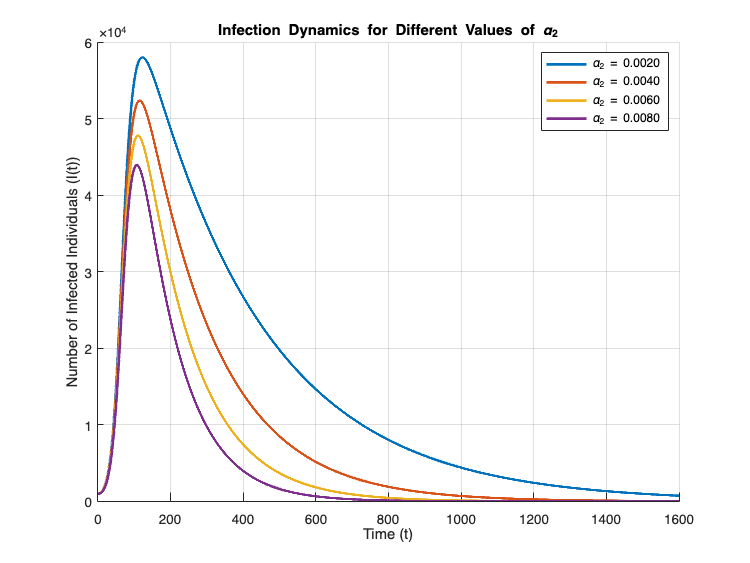


% Pergunta 2.3.2.a) -----------------------------------------------------
k = 5; 
a = 0; 
b = 1600; 
ya = [99000; 0; 1000; 0; 0]; 
n = b*10;  % número de passos no intervalo [0, 1600] com τ = 0.1
alpha_values = [0.002, 0.004, 0.006, 0.008];
t = linspace(a,b, n+1);
results_table_a = ones(length(alpha_values), length(t));

for I = 1:length(alpha_values) 
    tempFx = @(t, x) Fx232(t, x, alpha_values(I));
    [Y, M] = Heun(tempFx, ya, a, b, n, k);
    results_table_a(I, :) = Y(3, :); 
end

% Plotting do gráfico
figure; hold on;
colors = lines(length(alpha_values)); 
for I = 1:length(alpha_values)
    plot(t, results_table_a(I, :), 'Color', colors(I,:), 'LineWidth', 2, ...
         'DisplayName', sprintf('\\alpha_2 = %.4f', alpha_values(I)));
end
xlabel('Time (t)');
ylabel('Number of Infected Individuals (I(t))');
title('Infection Dynamics for Different Values of \alpha_2');
legend show;
grid on;
hold off;


% Pergunta 2.3.2.b) ----------------------------------------------------
k = 5; 
a = 0; 
b = 1600; 
ya = [99000; 0; 1000; 0; 0]; 
n = b*10;  % número de passos no intervalo [0, 1600] com τ = 0.1
alpha_values = [0.002, 0.004, 0.006, 0.008];
results_table_b = ones(k, length(alpha_values)); 

for I = 1:length(alpha_values) 
    tempFx = @(t, x) Fx232(t, x, alpha_values(I));
    [Y, M] = Heun(tempFx, ya, a, b, n, k);
    results_table_b(:, I) = M(:); 
end

results_table_b(3,:)'

ans = 1.0e+04 *

   5.800297569693762
   5.236557407518818
   4.779431168518623
   4.394250512804339


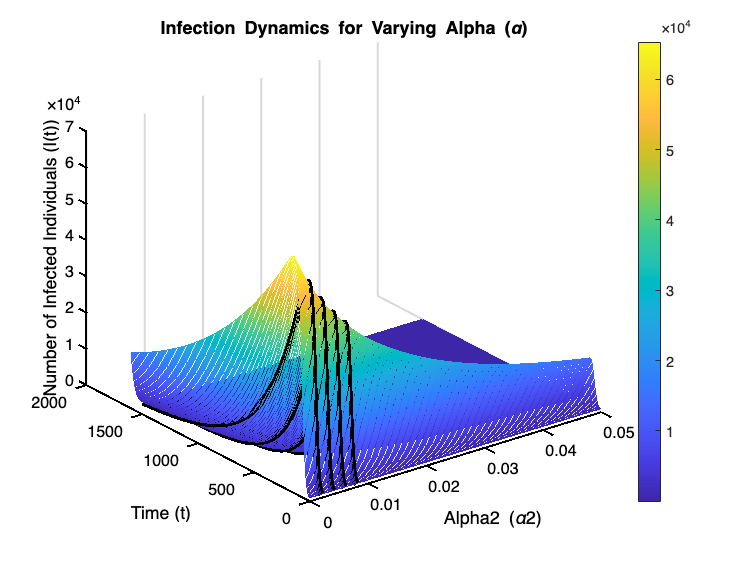

% Plotting do gráfico 3D do impacto da taxa de quarentena
k = 5;
a = 0; 
b = 1600; 
ya = [99000; 0; 1000; 0; 0];
n = b * 0.1; 
alpha_values = linspace(0, 0.05, 250); 
t = linspace(a, b, n + 1);
results_table_a = ones(length(alpha_values), length(t)); 

for I = 1:length(alpha_values)
    tempFx = @(t, x) Fx232(t, x, alpha_values(I));
    [Y, M] = Heun(tempFx, ya, a, b, n, k);
    results_table_a(I, :) = Y(3, :);
end

[T, A] = meshgrid(t, alpha_values);
figure;
surf(A, T, results_table_a, 'EdgeColor', 'interp', 'FaceAlpha', 0.1);
xlabel('Alpha2 (\alpha2)');
ylabel('Time (t)');
zlabel('Number of Infected Individuals (I(t))');
title('Infection Dynamics for Varying Alpha (\alpha)');
colorbar;
grid on;
ax = gca;
ax.FontSize = 12; 
ax.LineWidth = 1.5; 
ax.XColor = 'k'; ax.YColor = 'k'; 
ax.ZColor = 'k'; 
set(gca, 'XGrid', 'on', 'YGrid', 'off', 'ZGrid', 'off')

hold on;
alpha_lines = [0.002, 0.004, 0.006, 0.008];
for alpha_line = alpha_lines
    [~, idx] = min(abs(alpha_values - alpha_line));
    plot3(alpha_values(idx)*ones(1, length(t)), t, results_table_a(idx, :), 'k', 'LineWidth', 5);
end
hold off;